# Poles and Zeros of an Elliptic Lowpass Filter

For data sampled at 1000 Hz, plot the poles and zeros of a 4th-order elliptic lowpass digital filter with cutoff frequency 200 Hz, 3 dB of ripple in the passband, and 30 dB of attenuation in the stopband.

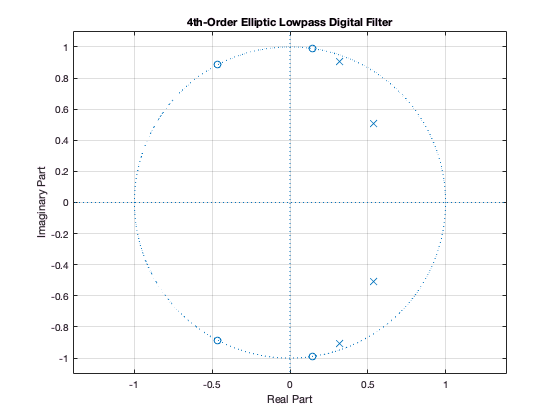

[z,p,k] = ellip(4,3,30,200/500);
zplane(z,p)
grid
title('4th-Order Elliptic Lowpass Digital Filter')

Create the same filter using `designfilt`. Use `fvtool` to plot its poles and zeros.

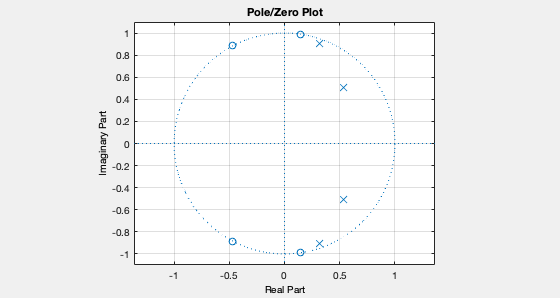

d = designfilt('lowpassiir','FilterOrder',4,'PassbandFrequency',200, ...
               'PassbandRipple',3,'StopbandAttenuation',30, ...
               'DesignMethod','ellip','SampleRate',1000);
zplane(d)

*Copyright 2015 The MathWorks, Inc.*